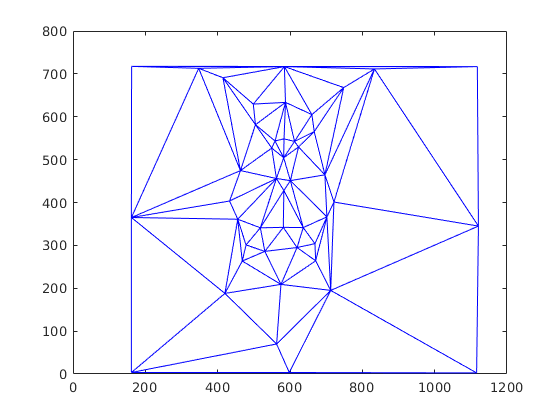

morphing1="src/coordinates/morphing1/frame0.csv";
morphing2="src/coordinates/morphing2/frame0.csv";

a=csvread(morphing1);
b=csvread(morphing2);

amesh=delaunay(a(:,1),a(:,2));
bmesh=delaunay(b(:,1),b(:,2));

c=zeros(45,2);

for i=1:45
    c(i,1)=(a(i,1)+b(i,1))*.5;
    c(i,2)=(a(i,2)+b(i,2))*.5;
end

cmesh=delaunay(c(:,1),c(:,2));
% triplot(cmesh(1:82,:),c(:,1),c(:,2));

moving=[1,2;3,4;7,6];
fixed=[2,1;4,3;5,6];
tform=fitgeotrans(moving,fixed,'affine');
disp(tform);

  affine2d with properties:

    Dimensionality: 2
                 T: [3×3 double]




moving=[a(cmesh(1,1),:);a(cmesh(1,2),:);a(cmesh(1,3),:)];
fixed=[c(cmesh(1,1),:);c(cmesh(1,2),:);c(cmesh(1,3),:)];
tform=fitgeotrans(moving,fixed,'affine');